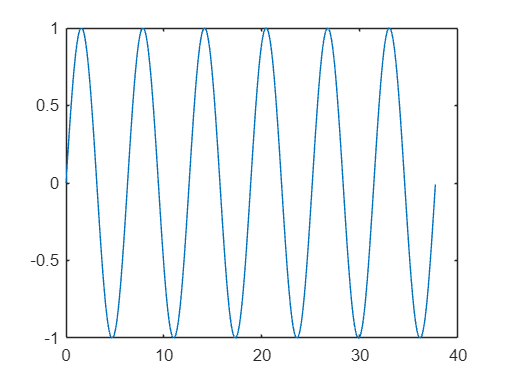

%% f(t)*sint(omega*t)的积分情况  如果初始相位正确，则结果正确，若不正确则结果不行
t = [0:0.01:12*pi];
omega = 1;
phi = 0;
f = sin(omega*t+phi);
plot(t,f)

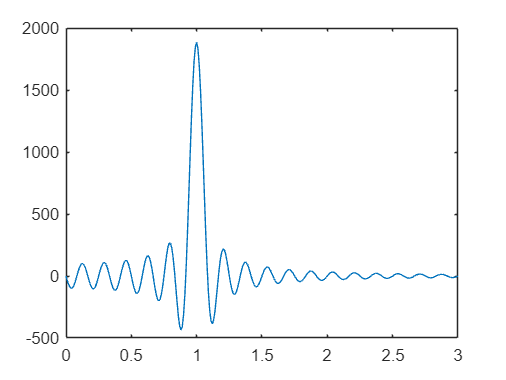


% w=2.02;
SgCall = [];
ww = 0:0.01:3;
for w = ww
g = f.*sin(w*t);
% plot(t,g)
Sg = sum(g);
SgCall = [SgCall,Sg];
end
plot(ww,SgCall)

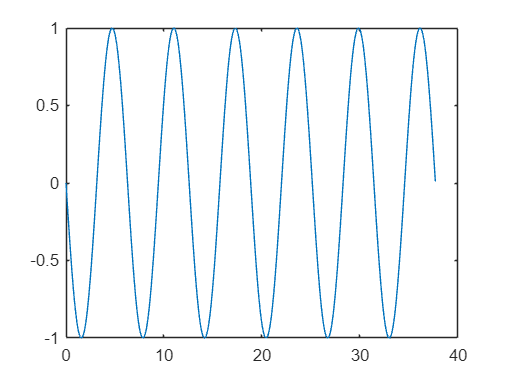

%% f(t)*exp(i*omega*t)的积分情况   可以避免初始相位问题
t = [0:0.01:12*pi];
omega = 1;
phi = pi/1;
f = sin(omega*t+phi);
plot(t,f)

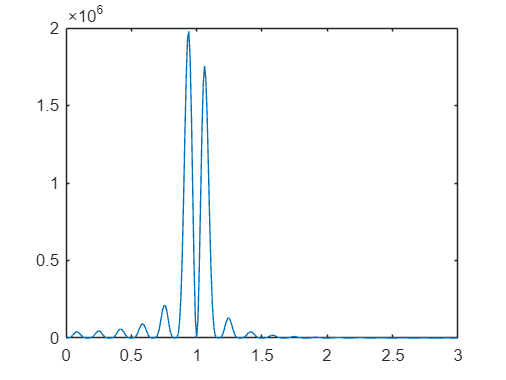


% w=2.02;
SImgCall = [];
SRegCall = [];
ww = 0:0.01:3;
for w = ww
Reg = f.*cos(w*t);
Img = f.*sin(w*t);
% plot(t,g)
SReg = sum(Reg);
SRegCall = [SRegCall,SReg];

SImg = sum(Img);
SImgCall = [SImgCall,SImg];
end
plot(ww,SRegCall.^2)  % cos 和 sin 在一个周期内正交  当周期很多的时候，可以忽略末尾不完整周期产生的影响

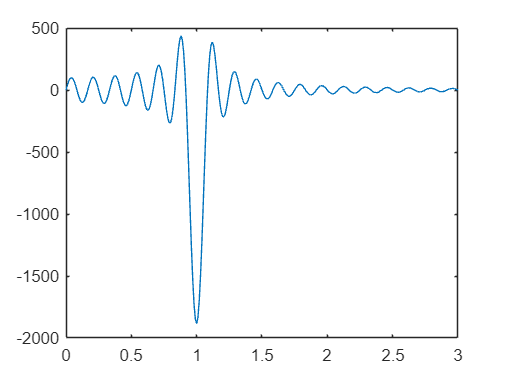

plot(ww,SImgCall)

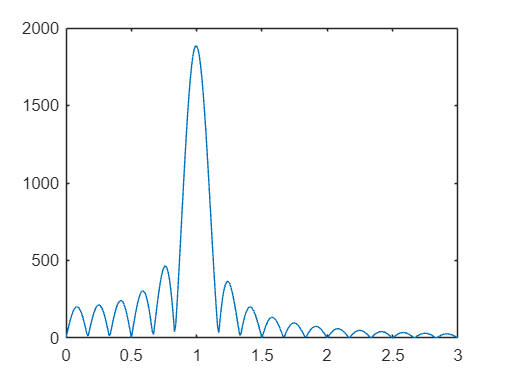

plot(ww,sqrt(SRegCall.^2+SImgCall.^2))

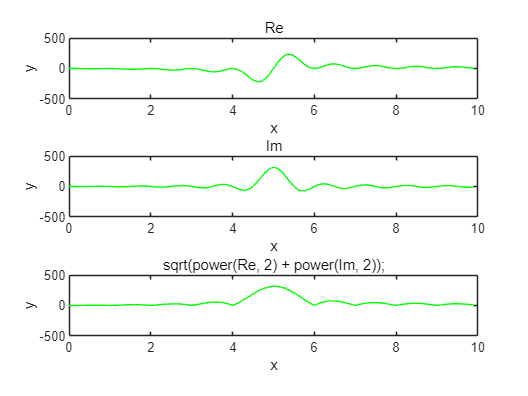


% 设置时间范围
t = 0:0.01:2*pi;
freq1 = 5;
freq2 = 0;
 
% 创建GIF文件
filename = 'sin_wave_animation.gif';
fps = 120;
 
% 初始化乘积结果的和
sum_of_product = zeros(1, length(t));
sum_of_product_sin = zeros(1, length(t));
sum_of_product_cos = zeros(1, length(t));

for i = 1:length(t)
    % 生成两个不同频率的正弦波
    y1 = cos(freq1 * t);
    y2 = sin((freq2+i/10) * t);
    y3 = cos((freq2+i/10) * t);
    % 计算两个正弦波的乘积
 
    y_product_sin = y1 .* y2;
    y_product_cos = y1 .* y3;
    % 计算乘积结果的和
    sum_of_product_sin(i+1) = sum(y_product_sin);
    sum_of_product_cos(i+1) =  sum(y_product_cos);
    
    sum_of_product = sqrt(power(sum_of_product_sin, 2) + power(sum_of_product_cos, 2));
 
    arr = 0:0.1:10;
    subplot(3, 1, 1);
    plot(arr(1:i), sum_of_product_sin(1:i), 'g'); % 只绘制当前时间点之前的数据
    xlabel('x');
    ylabel('y');
    xlim([0, 10]);
    ylim([-500, 500]);
    title('Re');
 
    arr = 0:0.1:10;
    subplot(3, 1, 2);
    plot(arr(1:i), sum_of_product_cos(1:i), 'g'); % 只绘制当前时间点之前的数据
    xlabel('x');
    ylabel('y');
    xlim([0, 10]);
    ylim([-500, 500]);
    title('Im');
    
    arr = 0:0.1:10;
    subplot(3, 1, 3);
    plot(arr(1:i), sum_of_product(1:i), 'g'); % 只绘制当前时间点之前的数据
    xlabel('x');
    ylabel('y');
    xlim([0, 10]);
    ylim([-500, 500]);
    title('sqrt(power(Re, 2) + power(Im, 2));');
 
    % 保存当前图像为GIF
    frame = getframe(gcf);
    im = frame2im(frame);
    [imind, cm] = rgb2ind(im, 256);
    if i == 1
        imwrite(imind, cm, filename, 'gif', 'Loopcount', inf, 'DelayTime', 1/fps);
    else
        imwrite(imind, cm, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 1/fps);
    end
    
    if i == 100
        break;
    end
 
end